# **BabelBrick**

**- Generating and presenting ****Synopsis**** of regular Latin verbs**

## **Introduction**

A highly inflectional language as it is, latin possesses strong verbs in the sense that they have a *large *quantity of forms, which are varied  according to the following properties:

- Person: $1^{\textrm{st}} ,2^{\textrm{nd}} ,3^{\textrm{rd}}$

- Number: *singular, plural*

- Time: *present, past, future*

- Aspect:* simple, progressive/repeated, completed*

- Voice: *active, passive*

- Mood:* indicative, imperative, subjunctive*

Unlike many modern Indo-European languages, whose verbs often take on identical forms in different cases (e.g. [de] wir lernten, sie lernten), or have auxiliary verbs to help with conjugation (e.g. [fr] avais chanté, avion chanté), latin verbs do the job all by themselves.

Max number of conjugations *in theory*


$$3*2*6*2*3=216$$


...which, can be overwhelming!

Thus, it would make perfect sence, if we were to go beyond the conventional 2D synopsis, and seek to generate a 3D representation instead. Here's how it works.

## Main

As is suggested in the description line, we decompose the task mainly into two steps: generating a list of conjugations from the 4 principle parts of a regular verb, and presenting selected sections on the 3D graph.

Since generation comes first, it is handled by writing the logic out extensively in underlying functions. In the main function however, we mostly handle the latter part of representation.

### Representation

#### Color settings

Color is used as an extra dimension to emphasize the shift of properties, namely:

- blue / orange:  active / passive

- dark -> bright:  present -> future, 1st -> 3nd

global x;
global y;
global z;
x = 0:1:5;
y = 0:1:5;
z = 0:1:5;
% colors
global blue1; % dark blue
global blue2; % light blue
global orange1; % dark orange
global orange2; % light orange
blue1 = [0 .4 1];
blue2 = [0.3010 0.745 0.933];%[0.3010 0.745 0.933];
orange1 = [.9 .4 .2];
orange2 = [1 .6 .5];

#### Axes & Indices

Positions are determined by properties. Axes are laid out as:

- X: Voice $\times$ Mood

- Y: Tense (Time $\times$ Aspect)

- Z: Person $\times$ Number

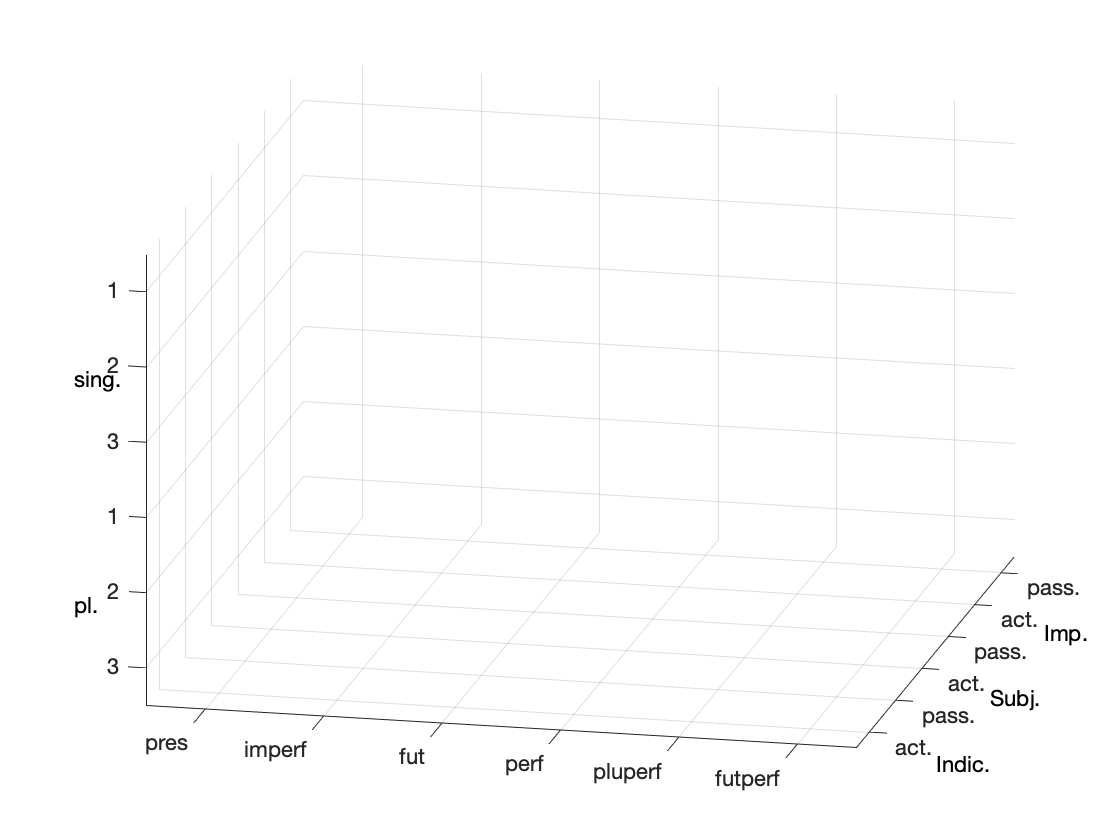

meshgrid(x,y,z);
[caz,cel] = view([-9 -2 4]); % camera angle
grid on;

axis([0 6 0 6 0 6]);
xticks(0.5:1:5.5)
xticklabels({'act.','pass.','act.','pass.','act.','pass.'})
yticks(0.5:1:5.5)
yticklabels({'futperf','pluperf','perf','fut','imperf','pres'})
zticks(0.5:1:5.5)
zticklabels({3,2,1,3,2,1})
text(-.5,6.5,4.5,'sing.');
text(-.5,6.5,1.5,'pl.');
text(.8,-.5,-.5,'Indic.');
text(2.85,-.5,-.5,'Subj.');
text(4.9,-.5,-.5,'Imp.');

### Generation

Have set out the plot framework, we now take a closer look at the content to be ploted. In latin we have 4 different families of conjugations. Here are some characteristic examples:

- 'vocō','vocāre','vocāvī','vocātus'

- 'moveō','movēre','mōvī','mōtus'

- 'regō','regere','rēxī','rēctus'            3.5 'capiō','capere','cēpī','captus'

- 'audiō','audīre','audīvī','audītus'

*Note that 3.5 is defined to be 3rd-i-stem (which resembles the pattern & is useful in the logic).

We will be using them also in later demonstrations.

#### Word Preparation

While balancing the tradeoff between *complexity* and *robustness*, we settled on using the conjugation number (1,2,3,3.5,4) and 4 principle parts as the starting point of synopsis generation i.e. the *key input* are to be structured as:

conj = 3.5;
parts = {'redeō','redīre','rediī','reditum'};

*redeō: go back, return

 A little formating before we go to get a corresponding title for the graph:

Dec = {'1^{st}','2^{nd}','3^{rd}','4^{th}'};
part = char(join(parts,','));
tit = {Dec{floor(conj)},part};
titf = (join(tit,': '));
title(titf,'Fontname','Bodoni');

#### Selecting Section

In order be able to select subsections to be ploted(or not), we defined the following adjustable parameters:

- $k_0$: person & number `[1,6]`

- $j_0$: tense `[1,6]`

- $i_0$: mood & voice `[1,4]`

- ${\textrm{Imp}}_I$: imperative, `dummy variable(0/1)`

**Ex1:** Full synopsis

k0 = 1:6;
j0 = 1:6;
i0 = 1:4;
Imp_I = 1;

**Ex2**: $3^{\textrm{rd}}$ person(sing.&pl.) pres.&imperf.&perf. subj.(act.&pass.), no imperative

k0 = [3,6];
j0 = [1:2,4];
i0 = 3:4;
Imp_I = 0;

*Detailed examples at document ending

Call already encapsulated func to plot the example:

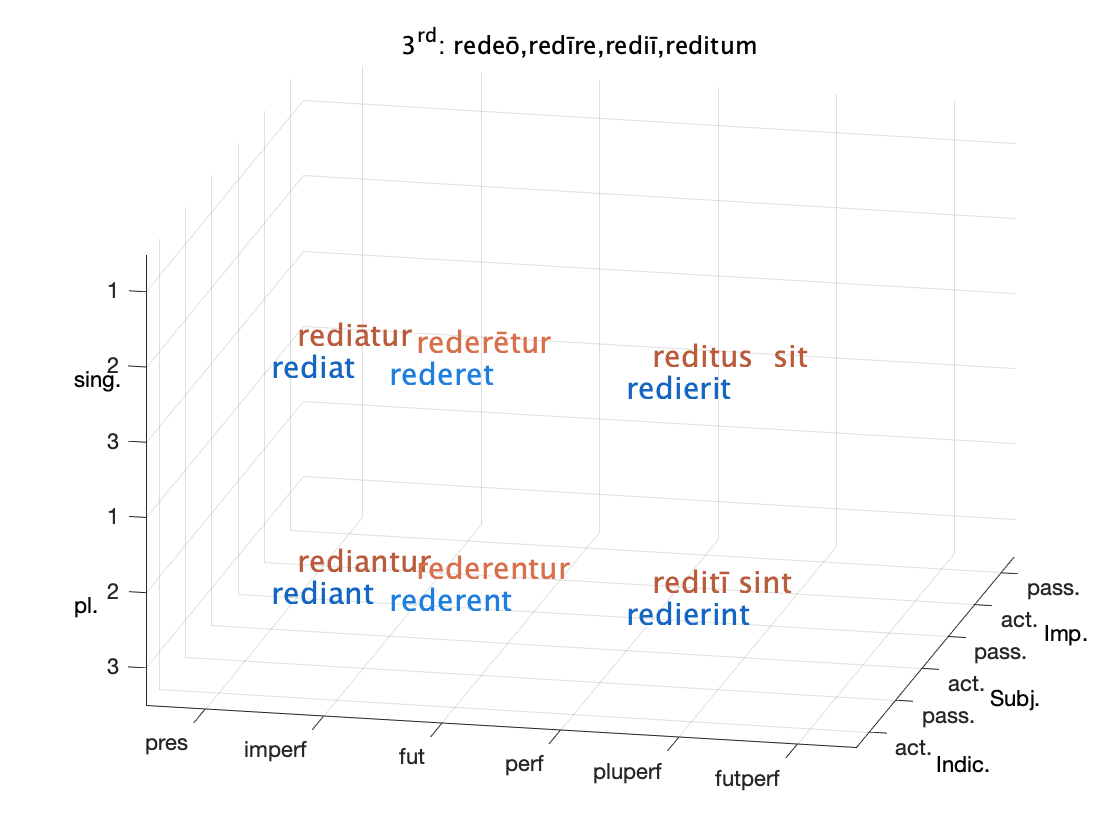

present_conjugation(conj,parts,k0,j0,i0,Imp_I);

## Functions

For a better insight into how the encapsulated functions are built, here is an overview of what is happening underneath:

- `present_conjugation:` takes in all words in indicative and subjunctive moods, calls `gen_conjugation,` outputs appended imperative mood and positioned words.

- `gen_conjugation:` inputs structured *key input*, calls all *tense generator* functions, outputs all words in indicative and subjunctive moods

List of tense generator functions (whose roles indicated per se):

- `gen_pres`

- `gen_imperf`

- `gen_fut`

- `gen_perf`

- `gen_pluperf`

- `gen_futperf`

## DEMOs

Select & match (group number with word) the 5 characteristic words:

conj = 2

conj = 2

parts = {'moveō','movēre','mōvī','mōtus'}

parts = 1×4 cell 数组
    {'moveō'}    {'movēre'}    {'mōvī'}    {'mōtus'}


### **Full conjugations: 5 groups**

Enable all rows and columns, rerun main function:

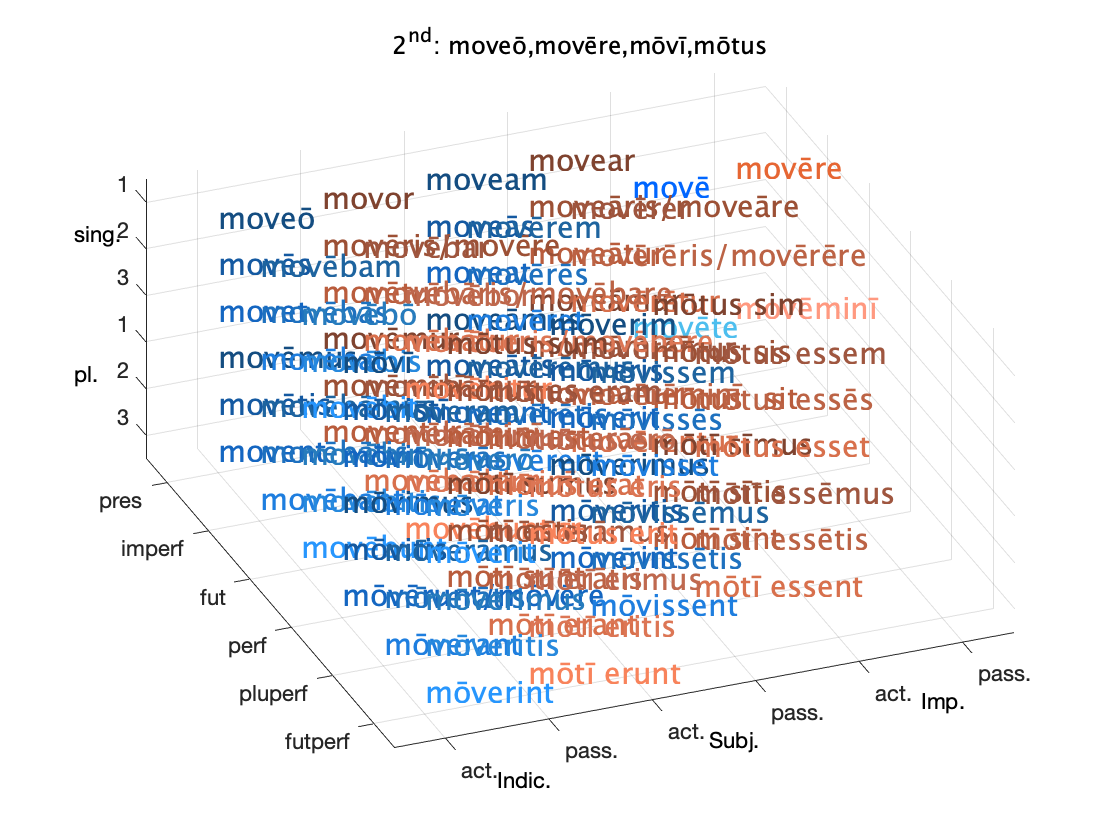

main_frame_plot(conj,parts)
view([-2 -5 6]); % camera angle
present_conjugation(conj,parts,1:6,1:6,1:4,1);

*To obtain a better view from the top level, the main function as illustrated in the first part is again encapsulated as `main_frame_plot.`

### Single Word Positioning

Modify position value to check its corresponding form:

k=5;
j=3;
i=2;

Rerun main function:

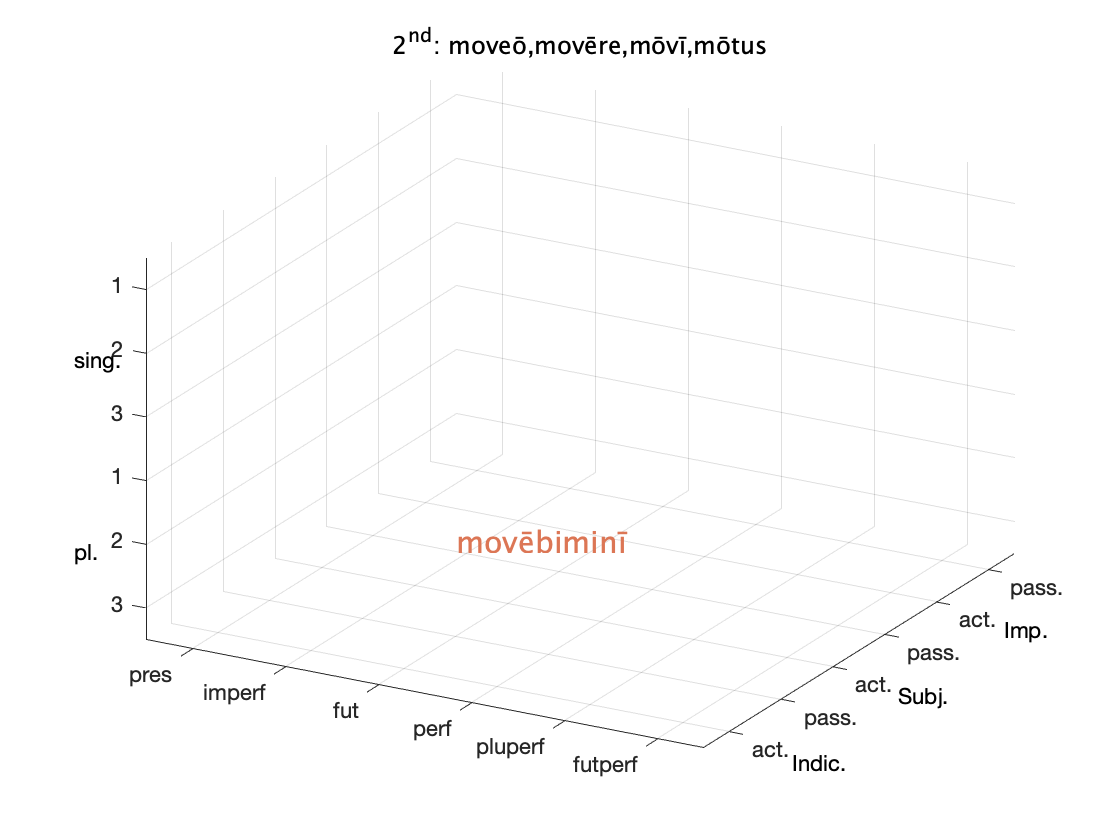

main_frame_plot(conj,parts)
view([-9 -5 6]); % camera angle
present_conjugation(conj,parts,k,j,i,0);

### Commonly Used Subparts

Pick a word (expanded list of 33 common words, copy and paste into input below):

- {'agō','agere','ēgī','āctus'}

- {'ambulō','ambulāre','ambulavī','ambulātum'}

- {'amō','amāre','amāvī','amātus'}

- {'audiō','audīre','audīvī','audītus'}

- {'canō','canere','cecinī','cantus'}

- {'capiō','capere','cēpī','captus'}

- {'debeō','debēre','dēbuī','dēbitus'}

- {'dīcō','dīcere','dīxī','dictus'}

- {'dōnō','dōnāre','dōnāvī','dōnātus'}

- {'dūcō','dūcere','dūxī','ducitus'}

- {'errō','errāre','errāvī','errātum'}

- {'faciō','facere','fēcī','factus'}

- {'gerō','gerere','gessī','gestus'}

- {'habeō','habēre','habuī','habitus'}

- {'iubeō','iubēre','iussī','iussus'}

- {'labōrō','labōrāre','labōrāvī','labōrātum'}

- {'laudō','laudāre','laudāvī','laudātus'}

- {'mittō','mittere','mīssī','missus'}

- {'mōnstrō','mōnstrāre','mōnstrāvī','mōnstrātus'}

- {'moveō','movēre','mōvī','mōtus'}

- {'optō','optāre','optāvī','optātus'}

- {'pōnō','pōnere','ponuī','positus'}

- {'pugnō','pugnāre','pugnāvī','pugnātum'}

- {'regō','regere','rēxī','rēctus'}

- {'respondeō','respondēre','respondī','respōnsus'}

- {'scrībō','scrībere','scrīpsī','scrīptus'}

- {'sentiō','sentīre','sēnsī','sēnsus'}

- {'superō','superāre','superāvī','superātus'}

- {'teneō','tenēre','tenuī','tentus'}

- {'veniō','venīre','vēnī','ventum'}

- {'videō','vidēre','vīdī','vīsus'}

- {'vinco','vincere','vīcī','victus'}

- {'vocō','vocāre','vocāvī','vocātus'}

conj = 1;
parts = {'superō','superāre','superāvī','superātus'};

#### by Person

Select corresponding Person $\times$ Number:

person = 3;

#### by Tense

Select corresponding Tense (Time $\times$ Aspect):

tense = 1:6;

#### **by Mood**

Select corresponding Mood:

mood = 1:4;
Imp_I = false;

Rerun main function:

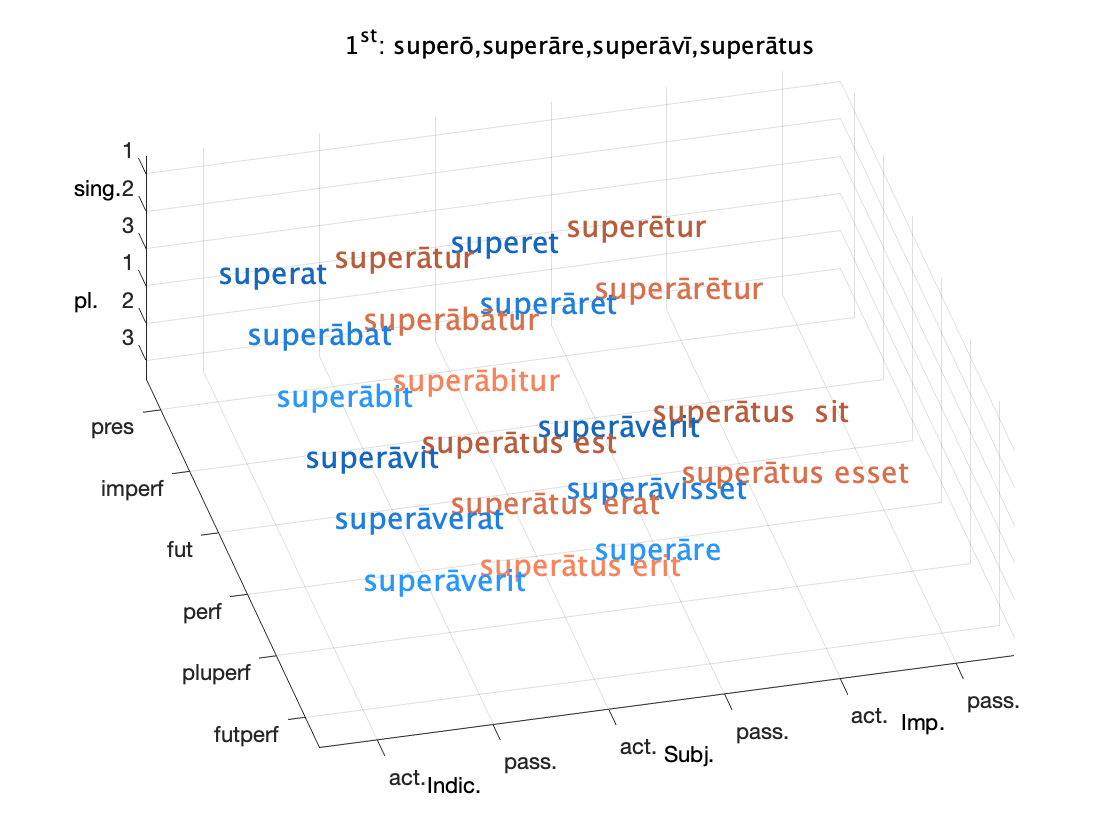

main_frame_plot(conj,parts)
view([-1 -4 7]); % camera angle
present_conjugation(conj,parts,person,tense,mood,Imp_I);